# Fit and Predict workspace firing from different models

## Add stuff to path

if(ispc)
    homeFolder = 'C:\Users\Raeed\';
else
    homeFolder = '/home/raeed/';
end
% addpath(genpath('C:\Users\Raeed\Projects\limblab\ClassyDataAnalysis'))
% addpath(genpath('/home/raeed/Projects/limblab/ClassyDataAnalysis'))
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'ClassyDataAnalysis']))
addpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'MultiWorkspace' filesep 'lib' filesep])
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'lib']))
cd([homeFolder 'Projects' filesep 'limblab' filesep 'data-raeed' filesep 'MultiWorkspace' filesep 'SplitWS' filesep 'Han' filesep '20160322' filesep 'area2' filesep])
% addpath('/home/raeed/Projects/limblab/proc-raeed/MultiWorkspace/lib/')
% cd('/home/raeed/Projects/limblab/data-raeed/MultiWorkspace/SplitWS/Han/20160322/area2/')

clear homeFolder

## Load CDS files

cds_files = dir(['CDS' filesep '*.mat']);

for i = 1:numel(cds_files)
    load(['CDS' filesep cds_files(i).name])
end

clear i
clear cds_files


## Add CDS files to experiments and bin data

% DL stuff
DL_ex = experiment();
% set variables to load from cds
DL_ex.meta.hasLfp=false;
DL_ex.meta.hashandleematics=true;
DL_ex.meta.hasForce=false;
DL_ex.meta.hasUnits=true;
DL_ex.meta.hasTrials=true;
DL_ex.meta.hasAnalog=true;
% add session to experiment
DL_ex.addSession(DL_cds);
% Bin experiment data
DL_ex.binConfig.include(1).field='units';
DL_ex.binConfig.include(1).which=find([DL_ex.units.data.ID]>0 & [DL_ex.units.data.ID]<255);
DL_ex.binConfig.include(2).field='kin';
DL_ex.binConfig.include(2).which={};
DL_ex.binConfig.include(3).field='analog';
DL_ex.binConfig.include(3).which=DL_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
DL_ex.firingRateConfig.cropType='tightCrop';
DL_ex.firingRateConfig.offset=-0.015;

DL_ex.binData()

% PM stuff
PM_ex = experiment();
% set variables to load from cds
PM_ex.meta.hasLfp=false;
PM_ex.meta.hasKinematics=true;
PM_ex.meta.hasForce=false;
PM_ex.meta.hasUnits=true;
PM_ex.meta.hasTrials=true;
PM_ex.meta.hasAnalog=true;
% add session to experiment
PM_ex.addSession(PM_cds);
PM_ex.binConfig.include(1).field='units';
PM_ex.binConfig.include(1).which=find([PM_ex.units.data.ID]>0 & [PM_ex.units.data.ID]<255);
PM_ex.binConfig.include(2).field='kin';
PM_ex.binConfig.include(2).which={};
PM_ex.binConfig.include(3).field='analog';
PM_ex.binConfig.include(3).which=PM_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
PM_ex.firingRateConfig.cropType='tightCrop';
PM_ex.firingRateConfig.offset=-0.015;

PM_ex.binData()


## Clear CDS

clear *_cds


## Get overall PDs for DL workspace

tic;

DL_ex.bin.pdConfig.method = 'glm';
DL_ex.bin.pdConfig.pos = false;
DL_ex.bin.pdConfig.vel = true;
DL_ex.bin.pdConfig.force = false;
DL_ex.bin.pdConfig.speed = false;
DL_ex.bin.pdConfig.bootstrapReps = 100;
DL_ex.bin.fitPds()

toc


## Get overall PDs for PM workspace

tic;

PM_ex.bin.pdConfig.method = 'glm';
PM_ex.bin.pdConfig.pos = false;
PM_ex.bin.pdConfig.vel = true;
PM_ex.bin.pdConfig.force = false;
PM_ex.bin.pdConfig.speed = false;
PM_ex.bin.pdConfig.bootstrapReps = 100;
PM_ex.bin.fitPds()

toc


## Find units that we care about

%extract relevant information
dirCIPM = PM_ex.bin.pdData.velDirCI;
dirCIDL = DL_ex.bin.pdData.velDirCI;

% calculate CI widths
DLCIwidth = diff(dirCIDL,1,2); % get CI widths
PMCIwidth = diff(dirCIPM,1,2);
DLCIwidth(DLCIwidth<0) = DLCIwidth(DLCIwidth<0)+2*pi;
PMCIwidth(PMCIwidth<0) = PMCIwidth(PMCIwidth<0)+2*pi;
tunedNeurons = DLCIwidth<pi/4 & PMCIwidth<pi/4;

clear dirCIPM
clear dirCIDL
clear DLCIwidth
clear PMCIwidth

## Extract the binned tables from each workspace experiment

% These are tables, binned at 50 ms
% PMdata = PM_ex.bin.data;
% DLdata =  DL_ex.bin.data;

% Portion out extrinsic coordinates, joints, muscles, neurons, and time
timeIDX = 1;
velIDX = contains(PM_ex.bin.data.Properties.VariableNames,'vx') | contains(PM_ex.bin.data.Properties.VariableNames,'vy');
% muscleIDX = 24:62;
muscleVelIDX = contains(PM_ex.bin.data.Properties.VariableNames,'muscleVel');
neurIDX = contains(PM_ex.bin.data.Properties.VariableNames,'LeftS1Area2CH');

% times
tPM = PM_ex.bin.data(:,timeIDX);
tDL = DL_ex.bin.data(:,timeIDX);
% handle position, velocity
handleVelPM = PM_ex.bin.data(:,velIDX);
handleVelDL = DL_ex.bin.data(:,velIDX);
% joints
% jointPM = PMdata(:,jointIDX);
% jointDL = DLdata(:,jointIDX);
% muscles
% musclePM = PMdata(:,muscleIDX);
% muscleDL = DLdata(:,muscleIDX);
muscleVelPM = PM_ex.bin.data(:,muscleVelIDX);
muscleVelDL = DL_ex.bin.data(:,muscleVelIDX);
% neurons
neurPM = PM_ex.bin.data(:,neurIDX);
neurDL = DL_ex.bin.data(:,neurIDX);

% extract only tuned neurons
neurPM = neurPM(:,tunedNeurons);
neurDL = neurDL(:,tunedNeurons);

clear *IDX



## Load in TRC files for marker data

clear egoCoords
markers = dlmread(['OpenSim' filesep 'Han_20160322_RW_PM_area2_002.trc'],'\t',6,0);
[egoCoords(:,1),egoCoords(:,2)] = cart2pol(markers(:,5),markers(:,3)); % get handle x and y in terms of shoulder origin
markertimes = markers(:,2);
egoCoords = interp1(markertimes,egoCoords,tPM.t);
egoTablePM = array2table(egoCoords,'VariableNames',{'egoTheta','egoRadius'});

clear egoCoords
markers = dlmread(['OpenSim' filesep 'Han_20160322_RW_DL_area2_001.trc'],'\t',6,0);
[egoCoords(:,1),egoCoords(:,2)] = cart2pol(markers(:,5),markers(:,3)); % get handle x and y in terms of shoulder origin
markertimes = markers(:,2);
egoCoords = interp1(markertimes,egoCoords,tDL.t);
egoTableDL = array2table(egoCoords,'VariableNames',{'egoTheta','egoRadius'});

clear markers
clear egoCoords
clear markertimes

## Clear experiments for memory

% clear *_ex

## Look at PCA on muscles to examine covariance patterns

% [~,~,~,~,explainedPM] = pca(muscleVelPM.Variables);
% [~,~,~,~,explainedDL] = pca(muscleVelDL.Variables);
[~,muscleScores,~,~,explained] =  pca([muscleVelPM.Variables;muscleVelDL.Variables]);

% convert scores to table
muscleScoresTable = array2table(muscleScores);

% Decompose score from PCA into workspaces
scorePM = muscleScoresTable(1:height(tPM),1:5);
scoreDL = muscleScoresTable(height(tPM)+1:end,1:5);

## Plot PCA results

97.42% of variance is explained by the first 5 principle components

% figure
% subplot(211)
% bar(explainedPM) % Variance explained by each PC
% 
% subplot(212)
% bar(cumsum(explainedPM)) % Cumulative variace explained by PCs
% ylim([0 100])
% 
% %Same for DL
% figure
% subplot(211)
% bar(explainedDL) % Variance explained by each PC
% 
% subplot(212)
% bar(cumsum(explainedDL)) % Cumulative variace explained by PCs
% ylim([0 100])
% 
% %Both together
% figure
% subplot(211)
% bar(explained) % Variance explained by each PC
% 
% subplot(212)
% bar(cumsum(explained)) % Cumulative variace explained by PCs
% ylim([0 100])

## Compose data tables with relevant covariates and tuned neurons only

% create workspace ID column for table: PM = 0, DL = 1
workspaceIDPM = table(zeros(height(tPM),1),'VariableNames',{'workspaceID'});
workspaceIDDL = table(ones(height(tDL),1),'VariableNames',{'workspaceID'});

PMdataTable = [tPM workspaceIDPM handleVelPM scorePM egoTablePM neurPM];
DLdataTable = [tDL workspaceIDDL handleVelDL scoreDL egoTableDL neurDL];

% clean up
clear muscleScore*
clear explained*
clear tPM
clear tDL
clear score*
clear handleVel*
clear muscleVel*
clear neur*
clear workspaceID*
clear egoTable*

## Fit GLM to kinematics in each workspace and predict neural firing rates (for cross-validation)

Pseudocode:

- 10-fold cross-validation

- * First get set of indices for cross-val

- * For each fold:

- ** compose binned data objects for training set (combined PM and DL) and testing set (separate PM and DL)

- ** **Training**

- ** fit GLM to handle velocity (training)

- ** fit GLM to PCAd muscle velocity (training)

- ** fit GLM to egocentric velocity (training)

- ** **Testing**

- ** use handle GLM to predict neural firing (testing PM and DL) -- place into binned data object

- ** use muscle GLM to predict neural firing (testing PM and DL) -- place into binned data object

- ** use egocentric GLM to predict neural firing (testing PM and DL) -- place into binned data object

- ** fit GLM to handle velocity (testing) for actual PDs (PM and DL) -- SAVE

- ** fit GLM to handle velocity (testing) for predicted handle neuron PDs (PM and DL) -- SAVE

- ** fit GLM to handle velocity (testing) for predicted muscle neuron PDs (PM and DL) -- SAVE

- ** fit GLM to handle velocity (testing) for predicted egocentric neuron PDs (PM and DL) -- SAVE

- ** get PD difference for true neurons -- SAVE

- ** get PD difference for handle neurons -- SAVE

- ** get PD difference for muscle neurons -- SAVE

- ** get PD difference for egocentric neurons -- SAVE

- ** get pseudo R2 for handle neurons -- SAVE

- ** get pseudo R2 for muscle neurons -- SAVE

- ** get pseudo R2 for egocentric neurons -- SAVE

- * end loop

Streamlined pseudocode:

- 10-fold cross-validations

- * First get set of indices for cross-val

- * For each fold:

- ** compose binned data objects for training set (combined PM and DL) and testing set (separate PM and DL)

- ** fit GLM to handle velocity (testing) for actual PDs (PM and DL) -- **SAVE**

- **** **get PD difference for true neurons -- **SAVE**

- ** For each model (handle, muscle, egocentric):

- *** **Training**

- ***** **Fit GLM to model (training)

- *** **Testing**

- ***** **Use model GLM to predict neural firing (testing PM and DL) -- place into another testing binnedData object

- *** fit GLM to handle velocity (testing) for predicted neuron PDs (PM and DL) -- **SAVE**

- ***** **get PD difference for model neurons -- **SAVE**

- ***** **get pseudoR2 for model neurons -- **SAVE**

- ****** end model loop

- * end fold loop

% set up for crossval
numRepeats = 10;
numFolds = 10;
numCrossvals = numRepeats*numFolds;
neurIDX = contains(PMdataTable.Properties.VariableNames,'LeftS1Area2CH');
numNeur = sum(neurIDX);

% Initialize output variables
sampleResultsTable = array2table(zeros(numCrossvals,numNeur),'VariableNames',PMdataTable.Properties.VariableNames(neurIDX));

% initialize PD prediction table
PDsPM = sampleResultsTable;
PDsDL = sampleResultsTable;
%                 handle model       muscle model       ego model
modelPredPDsPM = {sampleResultsTable,sampleResultsTable,sampleResultsTable};
modelPredPDsDL = {sampleResultsTable,sampleResultsTable,sampleResultsTable};

% initialize PD diff tables
diffPDs = sampleResultsTable;
%               handle model       muscle model       ego model
modelDiffPDs = {sampleResultsTable,sampleResultsTable,sampleResultsTable};

% Initialize pseudoR2 table
%            handle model       muscle model       ego model
modelR2PM = {sampleResultsTable,sampleResultsTable,sampleResultsTable};
modelR2DL = {sampleResultsTable,sampleResultsTable,sampleResultsTable};

clear sampleResultsTable;
clear neurIDX;
clear numNeur;

% save general PD config for use in new binnedData objects
genPDConfig.method = 'glm';
genPDConfig.glmNoiseModel = 'poisson';
genPDConfig.pos = false;
genPDConfig.vel = true;
genPDConfig.force = false;
genPDConfig.speed = false;
genPDConfig.units = [];
genPDConfig.windows = [];
genPDConfig.bootstrap = false;
genPDConfig.useParallel = false;
genPDConfig.verbose = false;
genPDConfig.bootstrapReps = 0;

% save handle covar config
handleCovarConfig.method = 'glm';
handleCovarConfig.glmNoiseModel = 'poisson';
handleCovarConfig.covarFilter = {'workspaceID','vx','vy'};
handleCovarConfig.units = [];
handleCovarConfig.windows = [];
handleCovarConfig.bootstrap = false;
handleCovarConfig.verbose = false;
handleCovarConfig.bootstrapReps = 0;
handleCovarConfig.useParallel = false;
handleCovarConfig.outputModelClass = true;

% save muscle covar config
muscleCovarConfig.method = 'glm';
muscleCovarConfig.glmNoiseModel = 'poisson';
muscleCovarConfig.covarFilter = {'workspaceID','muscleScores1','muscleScores2','muscleScores3','muscleScores4','muscleScores5'};
muscleCovarConfig.units = [];
muscleCovarConfig.windows = [];
muscleCovarConfig.bootstrap = false;
muscleCovarConfig.verbose = false;
muscleCovarConfig.bootstrapReps = 0;
muscleCovarConfig.useParallel = false;
muscleCovarConfig.outputModelClass = true;

% save ego covar config
egoCovarConfig.method = 'glm';
egoCovarConfig.glmNoiseModel = 'poisson';
egoCovarConfig.covarFilter = {'workspaceID','egoTheta','egoRadius'};
egoCovarConfig.units = [];
egoCovarConfig.windows = [];
egoCovarConfig.bootstrap = false;
egoCovarConfig.verbose = false;
egoCovarConfig.bootstrapReps = 0;
egoCovarConfig.useParallel = false;
egoCovarConfig.outputModelClass = true;

% combine covar configs into cell array
covariateConfigs = {handleCovarConfig;muscleCovarConfig;egoCovarConfig};

% initialize intermediate binnedData objects
trainData = binnedData();
testDataPM = binnedData();
testDataPM.pdConfig = genPDConfig;
testDataDL = binnedData();
testDataDL.pdConfig = genPDConfig;
predDataPM = binnedData();
predDataPM.pdConfig = genPDConfig;
predDataDL = binnedData();
predDataDL.pdConfig = genPDConfig;

% clean up
clear genPDConfig
clear handleCovarConfig
clear muscleCovarConfig


## Run cross-validation

% repeat some number of times

tic;

time = toc;
for crossvalctr = 1:numRepeats

    % get folds
    foldidxPM = crossvalind('Kfold',height(PMdataTable),numFolds);

    foldidxDL = crossvalind('Kfold',height(DLdataTable),numFolds);
    

    % loop over folds
    for foldctr = 1:numFolds
        % get output idx
        outputIDX = numFolds*(crossvalctr-1)+foldctr;
        % extract training and test indices
        testidxPM = (foldidxPM == foldctr);
        trainidxPM = (foldidxPM ~= foldctr);
        testidxDL = (foldidxDL == foldctr);
        trainidxDL = (foldidxDL ~= foldctr);
        
        % compose binnedData object for training
        trainData.updateBins([PMdataTable(trainidxPM,:);DLdataTable(trainidxDL,:)]);
        
        % compose binnedData objects for testing
        testDataPM.updateBins(PMdataTable(testidxPM,:));
        testDataDL.updateBins(DLdataTable(testidxDL,:));
        
        % get actual PDs and PD difference
        testDataPM.fitPds();
        testDataDL.fitPds();
        
        %extract relevant information
        dirPM = testDataPM.pdData.velDir;
        dirDL = testDataDL.pdData.velDir;
        diffPD = dirDL-dirPM;
        diffPD(diffPD<-pi) = diffPD(diffPD<-pi)+2*pi;
        diffPD(diffPD>pi) = diffPD(diffPD>pi)-2*pi;
        % save things
        PDsPM{outputIDX,:} = dirPM';
        PDsDL{outputIDX,:} = dirDL';
        diffPDs{outputIDX,:} = diffPD';
        
        for modelctr = 1:numel(covariateConfigs)
            % fit models to training data (need to write GLM code)
            trainData.covariateConfig = covariateConfigs{modelctr};
            trainData.fitCovariates();
            
            % predict neural activity in testing data
            [predDataTablePM,PMR2] = neuronPredict(trainData.covariateData.model,testDataPM.data);
            [predDataTableDL,DLR2] = neuronPredict(trainData.covariateData.model,testDataDL.data);
            
            % update bins for predicted binned data objects
            predDataPM.updateBins(predDataTablePM);
            predDataDL.updateBins(predDataTableDL);
            
            % get predicted PDs and PD difference
            predDataPM.fitPds();
            predDataDL.fitPds();
            
            % Save things
            dirPM = predDataPM.pdData.velDir;
            dirDL = predDataDL.pdData.velDir;
            diffPD = dirDL-dirPM;
            diffPD(diffPD<-pi) = diffPD(diffPD<-pi)+2*pi;
            diffPD(diffPD>pi) = diffPD(diffPD>pi)-2*pi;
            % save things
            modelPredPDsPM{modelctr}{outputIDX,:} = dirPM';
            modelPredPDsDL{modelctr}{outputIDX,:} = dirDL';
            modelDiffPDs{modelctr}{outputIDX,:} = diffPD';
            modelR2PM{modelctr}(outputIDX,:) = PMR2;
            modelR2DL{modelctr}(outputIDX,:) = DLR2;
        end
    end
end
toc

clear trainData
clear testData*
clear dirPM
clear dirDL
clear diffPD
clear foldidx*
clear *ctr
clear outputIDX
clear *idx*
clear predDataTable*
clear numCrossvals
clear numFolds
clear numRepeats


## Combine output data into mean and confidence intervals

% R2 first
for modelctr = 1:length(modelR2PM)

Elapsed time is 3992.443525 seconds.


    % R2 first
    modelR2PMmean{modelctr} = mean(modelR2PM{modelctr}.Variables);
    modelR2PMCI{modelctr} = prctile(modelR2PM{modelctr}.Variables,[2.5;97.5]);
    modelR2DLmean{modelctr} = mean(modelR2DL{modelctr}.Variables);
    modelR2DLCI{modelctr} = prctile(modelR2DL{modelctr}.Variables,[2.5;97.5]);
    
    % diff PDs
    modelDiffPDsmean{modelctr} = circ_mean(modelDiffPDs{modelctr}.Variables);
    centeredDirs = modelDiffPDs{modelctr}.Variables-repmat(modelDiffPDsmean{modelctr},height(modelDiffPDs{modelctr}),1);
    centeredDirs(centeredDirs<-pi) =  centeredDirs(centeredDirs<-pi)+2*pi;
    centeredDirs(centeredDirs>pi) = centeredDirs(centeredDirs>pi)-2*pi;
    modelDiffPDsRelCI{modelctr} = prctile(centeredDirs,[2.5;97.5]);
    
    % actual PDs
    meandirs = circ_mean(modelPredPDsPM{modelctr}.Variables);
    centeredDirs = modelPredPDsPM{modelctr}.Variables-repmat(meandirs,height(modelPredPDsPM{modelctr}),1);
    centeredDirs(centeredDirs<-pi) =  centeredDirs(centeredDirs<-pi)+2*pi;
    centeredDirs(centeredDirs>pi) = centeredDirs(centeredDirs>pi)-2*pi;
    dirCIs = prctile(centeredDirs,[2.5;97.5]);
    modelPredPDsPMtable{modelctr} = table(meandirs',dirCIs','VariableNames',{'velDir','velDirCI'});
    
    meandirs = circ_mean(modelPredPDsDL{modelctr}.Variables);
    centeredDirs = modelPredPDsDL{modelctr}.Variables-repmat(meandirs,height(modelPredPDsDL{modelctr}),1);
    centeredDirs(centeredDirs<-pi) =  centeredDirs(centeredDirs<-pi)+2*pi;
    centeredDirs(centeredDirs>pi) = centeredDirs(centeredDirs>pi)-2*pi;
    dirCIs = prctile(centeredDirs,[2.5;97.5]);
    modelPredPDsDLtable{modelctr} = table(meandirs',dirCIs','VariableNames',{'velDir','velDirCI'});
end
% diff PDs
diffPDsMean = circ_mean(diffPDs.Variables);
centeredDirs = diffPDs.Variables-diffPDsMean;
centeredDirs(centeredDirs<-pi) =  centeredDirs(centeredDirs<-pi)+2*pi;
centeredDirs(centeredDirs>pi) = centeredDirs(centeredDirs>pi)-2*pi;
diffPDsRelCI = prctile(centeredDirs,[2.5;97.5]);

meandirs = circ_mean(PDsPM.Variables);
centeredDirs = PDsPM.Variables-repmat(meandirs,height(PDsPM),1);
centeredDirs(centeredDirs<-pi) =  centeredDirs(centeredDirs<-pi)+2*pi;
centeredDirs(centeredDirs>pi) = centeredDirs(centeredDirs>pi)-2*pi;
dirCIs = prctile(centeredDirs,[2.5;97.5]);
PDsPMtable = table(meandirs',dirCIs','VariableNames',{'velDir','velDirCI'});

meandirs = circ_mean(PDsDL.Variables);
centeredDirs = PDsDL.Variables-repmat(meandirs,height(PDsDL),1);
centeredDirs(centeredDirs<-pi) =  centeredDirs(centeredDirs<-pi)+2*pi;
centeredDirs(centeredDirs>pi) = centeredDirs(centeredDirs>pi)-2*pi;
dirCIs = prctile(centeredDirs,[2.5;97.5]);
PDsDLtable = table(meandirs',dirCIs','VariableNames',{'velDir','velDirCI'});

clear modelctr
clear meandirs
clear centeredDirs

## Predict tuning curves

% First get all tuning curves we want
[curvesPM,bins] = getTuningCurves(handleInputPMtest,neurPM{testingIdxPM,:});
[curvesDL,~] = getTuningCurves(handleInputDLtest,neurDL{testingIdxDL,:});


## Get predicted preferred directions (moved into first loop)

% samplePdTable = repmat(table(0,[0 0],'VariableNames',{'velDir','velDirCI'}),width(neurPM),1);
% 
% PdsPM = samplePdTable;
% PdsDL = samplePdTable;
% 
% % handlePredPdsPMfromPM = samplePdTable;
% % handlePredPdsDLfromDL = samplePdTable;
% % handlePredPdsPMfromDL = samplePdTable;
% % handlePredPdsDLfromPM = samplePdTable;
% handlePredPdsPMfromFull = samplePdTable;
% handlePredPdsDLfromFull = samplePdTable;
% 
% % musclePredPdsPMfromPM = samplePdTable;
% % musclePredPdsDLfromDL = samplePdTable;
% % musclePredPdsPMfromDL = samplePdTable;
% % musclePredPdsDLfromPM = samplePdTable;
% musclePredPdsPMfromFull = samplePdTable;
% musclePredPdsDLfromFull = samplePdTable;

% tic;
% for i = 1:width(neurPM)
%     % compose GLM outputs
%     outputPMtest = neurPM{testingIdxPM,i};
%     outputDLtest = neurDL{testingIdxDL,i};
%     
%     % bootstrap all fits
% %     handleModelPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputPMtest,outputPMtest);
% %     handleModelDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputDLtest,outputDLtest);
% %     
% %     handleModelPMfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputPMtest,handlePredNeurPMfromPM(:,i));
% %     handleModelDLfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputDLtest,handlePredNeurDLfromDL(:,i));
% %     handleModelPMfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputPMtest,handlePredNeurPMfromDL(:,i));
% %     handleModelDLfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputDLtest,handlePredNeurDLfromPM(:,i));
% %     handleModelPMfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputPMtest,handlePredNeurPMfromFull(:,i));
% %     handleModelDLfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputDLtest,handlePredNeurDLfromFull(:,i));
% %     
% %     muscleModelPMfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputPMtest,musclePredNeurPMfromPM(:,i));
% %     muscleModelDLfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputDLtest,musclePredNeurDLfromDL(:,i));
% %     muscleModelPMfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputPMtest,musclePredNeurPMfromDL(:,i));
% %     muscleModelDLfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputDLtest,musclePredNeurDLfromPM(:,i));
% %     muscleModelPMfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputPMtest,musclePredNeurPMfromFull(:,i));
% %     muscleModelDLfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),handleInputDLtest,musclePredNeurDLfromFull(:,i));
%     
%     % extract weights
%     
%     PdsPM(i,:) = calculatePDs(handleInputPMtest,outputPMtest,true,100);
%     PdsDL(i,:) = calculatePDs(handleInputDLtest,outputDLtest,true,100);
%     
% %     handlePredPdsPMfromPM(i,:) = calculatePDs(handleInputPMtest,handlePredNeurPMfromPM(:,i),true,100);
% %     handlePredPdsDLfromDL(i,:) = calculatePDs(handleInputDLtest,handlePredNeurDLfromDL(:,i),true,100);
% %     handlePredPdsPMfromDL(i,:) = calculatePDs(handleInputPMtest,handlePredNeurPMfromDL(:,i),true,100);
% %     handlePredPdsDLfromPM(i,:) = calculatePDs(handleInputDLtest,handlePredNeurDLfromPM(:,i),true,100);
%     handlePredPdsPMfromFull(i,:) = calculatePDs(handleInputPMtest,handlePredNeurPMfromFull(:,i),true,100);
%     handlePredPdsDLfromFull(i,:) = calculatePDs(handleInputDLtest,handlePredNeurDLfromFull(:,i),true,100);
%     
% %     musclePredPdsPMfromPM(i,:) = calculatePDs(handleInputPMtest,musclePredNeurPMfromPM(:,i),true,100);
% %     musclePredPdsDLfromDL(i,:) = calculatePDs(handleInputDLtest,musclePredNeurDLfromDL(:,i),true,100);
% %     musclePredPdsPMfromDL(i,:) = calculatePDs(handleInputPMtest,musclePredNeurPMfromDL(:,i),true,100);
% %     musclePredPdsDLfromPM(i,:) = calculatePDs(handleInputDLtest,musclePredNeurDLfromPM(:,i),true,100);
%     musclePredPdsPMfromFull(i,:) = calculatePDs(handleInputPMtest,musclePredNeurPMfromFull(:,i),true,100);
%     musclePredPdsDLfromFull(i,:) = calculatePDs(handleInputDLtest,musclePredNeurDLfromFull(:,i),true,100);
% end
% toc
    
% diffPD = PdsDL.velDir - PdsPM.velDir;
% diffPD(diffPD<-pi) = diffPD(diffPD<-pi)+2*pi;
% diffPD(diffPD>pi) = diffPD(diffPD>pi)-2*pi;
% 
% handlePredDiffPDfromFull = handlePredPdsDLfromFull.velDir - handlePredPdsPMfromFull.velDir;
% handlePredDiffPDfromFull(handlePredDiffPDfromFull<-pi) = handlePredDiffPDfromFull(handlePredDiffPDfromFull<-pi)+2*pi;
% handlePredDiffPDfromFull(handlePredDiffPDfromFull>pi) = handlePredDiffPDfromFull(handlePredDiffPDfromFull>pi)-2*pi;
% 
% musclePredDiffPDfromFull = musclePredPdsDLfromFull.velDir - musclePredPdsPMfromFull.velDir;
% musclePredDiffPDfromFull(musclePredDiffPDfromFull<-pi) = musclePredDiffPDfromFull(musclePredDiffPDfromFull<-pi)+2*pi;
% musclePredDiffPDfromFull(musclePredDiffPDfromFull>pi) = musclePredDiffPDfromFull(musclePredDiffPDfromFull>pi)-2*pi;


## Look at PM->PM fits

% figure
% plot(handleModelPMR2,muscleModelPMR2,'o')
% hold on
% plot([-1 1],[-1 1], 'k--','linewidth',2)
% plot([0 0],[-1 1],'k-','linewidth',1)
% plot([-1 1],[0 0],'k-','linewidth',1)
% xlabel('Kinematic Model Pseudo R^2 on PM workspace')
% ylabel('Muscle Model Pseudo R^2 on PM workspace')
% axis equal
% xlim([-0.5 0.5])
% ylim([-0.5 0.5])
% set(gca,'box','off','tickdir','out')


## Look at PM->DL fits

% figure
% plot(handleModelAcrossDLR2,muscleModelAcrossDLR2,'o')
% hold on
% plot([-1 1],[-1 1], 'k--','linewidth',3)
% plot([0 0],[-1 1],'k-','linewidth',1)
% plot([-1 1],[0 0],'k-','linewidth',1)
% xlabel('Kinematic Model (trained on PM) Pseudo R^2 on DL workspace')
% ylabel('Muscle Model (trained on PM) Pseudo R^2 on DL workspace')
% axis equal
% xlim([-0.5 0.5])
% ylim([-0.5 0.5])
% set(gca,'box','off','tickdir','out')

## Look at Full->PM,DL fits

figure
plot(modelR2PMmean{1},modelR2PMmean{2},'c^')
hold on
plot([-0.1 1],[-0.1 1], 'k--','linewidth',3)
plot([0 0],[-0.1 1],'k-','linewidth',1)
plot([-0.1 1],[0 0],'k-','linewidth',1)
plot(modelR2PMmean{1},modelR2PMmean{2},'c^')
xlabel('Kinematic Model Pseudo R^2 on PM workspace')
ylabel('Muscle Model Pseudo R^2 on PM workspace')
axis equal
xlim([-0.1 0.5])
ylim([-0.1 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])
figure
plot(modelR2PMmean{1},modelR2PMmean{2},'r^')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
plot(modelR2PMmean{1},modelR2PMmean{2},'r^')
xlabel('Kinematic Model Pseudo R^2 on DL workspace')
ylabel('Muscle Model Pseudo R^2 on DL workspace')
axis equal
xlim([-0.1 0.5])
ylim([-0.1 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])



## Full vs individual workspaces for handle and muscle models

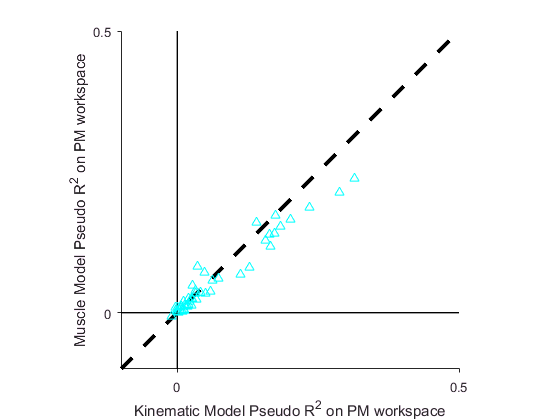

% figure
% plot(handleModelFullDLR2,handleModelDLR2,'r^')
% hold on
% plot([-1 1],[-1 1], 'k--','linewidth',3)
% plot([0 0],[-1 1],'k-','linewidth',1)
% plot([-1 1],[0 0],'k-','linewidth',1)
% plot(handleModelFullDLR2,handleModelDLR2,'r^')
% % xlabel('Kinematic Model Pseudo R^2 on DL workspace')
% % ylabel('Muscle Model Pseudo R^2 on DL workspace')
% axis equal
% xlim([-0.5 0.5])
% ylim([-0.5 0.5])
% set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])
% 

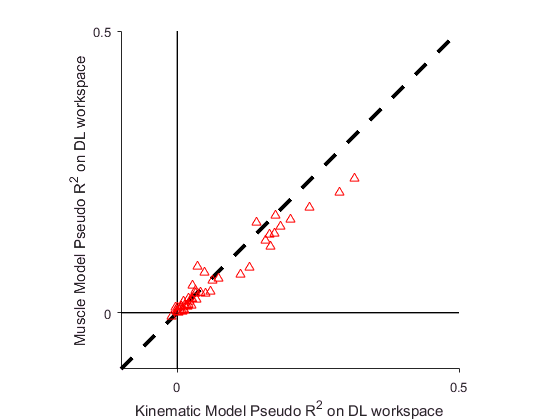

% figure
% plot(handleModelFullPMR2,handleModelPMR2,'m^')
% hold on
% plot([-1 1],[-1 1], 'k--','linewidth',3)
% plot([0 0],[-1 1],'k-','linewidth',1)
% plot([-1 1],[0 0],'k-','linewidth',1)
% plot(handleModelFullPMR2,handleModelPMR2,'m^')
% % xlabel('Kinematic Model Pseudo R^2 on DL workspace')
% % ylabel('Muscle Model Pseudo R^2 on DL workspace')
% axis equal
% xlim([-0.5 0.5])
% ylim([-0.5 0.5])
% set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

% 
% figure
% plot(muscleModelFullPMR2,muscleModelPMR2,'m^')
% hold on
% plot([-1 1],[-1 1], 'k--','linewidth',3)
% plot([0 0],[-1 1],'k-','linewidth',1)
% plot([-1 1],[0 0],'k-','linewidth',1)
% plot(muscleModelFullPMR2,muscleModelPMR2,'m^')
% % xlabel('handleematic Model Pseudo R^2 on DL workspace')
% % ylabel('Muscle Model Pseudo R^2 on DL workspace')
% axis equal
% xlim([-0.5 0.5])
% ylim([-0.5 0.5])
% set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])
% 
% figure
% plot(muscleModelFullDLR2,muscleModelDLR2,'r^')
% hold on
% plot([-1 1],[-1 1], 'k--','linewidth',3)
% plot([0 0],[-1 1],'k-','linewidth',1)
% plot([-1 1],[0 0],'k-','linewidth',1)
% plot(muscleModelFullDLR2,muscleModelDLR2,'r^')
% % xlabel('Kinematic Model Pseudo R^2 on DL workspace')
% % ylabel('Muscle Model Pseudo R^2 on DL workspace')
% axis equal
% xlim([-0.5 0.5])
% ylim([-0.5 0.5])
% set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

## Predict tuning curves within workspace using handle and muscle models

Find that muscle model seems to match the kinematic model tuning curves fairly well. Both predict the actual tuning curves decently.

% colorPM = [0.6 0.5 0.7];
% colorDL = [1 0 0];
% colorPredKin =  [0 1 0];
% colorPredMuscle = [0 0 1];
% 
% figure
% for i = 1:height(curvesPM)
%     clf
%     maxRad = max([curvesPM.binnedFR(i,:) handlePredCurvesPMfromPM.binnedFR(i,:) musclePredCurvesPMfromPM.binnedFR(i,:)]);
%     
%     plotTuning(bins,PdsPM(i,:),curvesPM(i,:),maxRad,colorPM)
%     hold on
%     plotTuning(bins,handlePredPdsPMfromPM(i,:),handlePredCurvesPMfromPM(i,:),maxRad,colorPredKin)
%     plotTuning(bins,musclePredPdsPMfromPM(i,:),musclePredCurvesPMfromPM(i,:),maxRad,colorPredMuscle)
%     title(['Neuron number: ' num2str(i)])
%     waitforbuttonpress
% end

## Same for DL

% for i = 1:height(curvesDL)
%     clf
%     maxRad = max([curvesDL.binnedFR(i,:) handlePredCurvesDLfromDL.binnedFR(i,:) musclePredCurvesDLfromDL.binnedFR(i,:)]);
%     
%     plotTuning(bins,PdsDL(i,:),curvesDL(i,:),maxRad,colorDL)
%     hold on
%     plotTuning(bins,handlePredPdsDLfromDL(i,:),handlePredCurvesDLfromDL(i,:),maxRad,colorPredKin)
%     plotTuning(bins,musclePredPdsDLfromDL(i,:),musclePredCurvesDLfromDL(i,:),maxRad,colorPredMuscle)
%     title(['Neuron number: ' num2str(i)])
%     waitforbuttonpress
% end

## Try predicting opposite workspace tuning curves

% for i = 1:height(curvesPM)
%     clf
%     maxRad = max([curvesPM.binnedFR(i,:) handlePredCurvesPMfromDL.binnedFR(i,:) musclePredCurvesPMfromDL.binnedFR(i,:)]);
%     
%     plotTuning(bins,PdsPM(i,:),curvesPM(i,:),maxRad,colorPM)
%     hold on
%     plotTuning(bins,handlePredPdsPMfromDL(i,:),handlePredCurvesPMfromDL(i,:),maxRad,colorPredKin)
%     plotTuning(bins,musclePredPdsPMfromDL(i,:),musclePredCurvesPMfromDL(i,:),maxRad,colorPredMuscle)
%     title(['Neuron number: ' num2str(i)])
%     waitforbuttonpress
% end

## Same for DL (opposite)

% for i = 1:height(curvesDL)
%     clf
%     maxRad = max([curvesDL.binnedFR(i,:) handlePredCurvesDLfromPM.binnedFR(i,:) musclePredCurvesDLfromPM.binnedFR(i,:)]);
%     
%     plotTuning(bins,PdsDL(i,:),curvesDL(i,:),maxRad,colorDL)
%     hold on
%     plotTuning(bins,handlePredPdsDLfromPM(i,:),handlePredCurvesDLfromPM(i,:),maxRad,colorPredKin)
%     plotTuning(bins,musclePredPdsDLfromPM(i,:),musclePredCurvesDLfromPM(i,:),maxRad,colorPredMuscle)
%     title(['Neuron number: ' num2str(i)])
%     waitforbuttonpress
% end

## Plot PM-DL comparison tuning curves

% % figure
% % for i = 1:height(curvesDL)
% %     clf
% %     maxRad = max([curvesPM.binnedFR(i,:) curvesDL.binnedFR(i,:)...
% %         handlePredCurvesDLfromPM.binnedFR(i,:) musclePredCurvesDLfromPM.binnedFR(i,:)...
% %         handlePredCurvesPMfromPM.binnedFR(i,:) musclePredCurvesPMfromPM.binnedFR(i,:)...
% %         handlePredCurvesPMfromDL.binnedFR(i,:) musclePredCurvesPMfromDL.binnedFR(i,:)...
% %         handlePredCurvesDLfromDL.binnedFR(i,:) musclePredCurvesDLfromDL.binnedFR(i,:)...
% %         handlePredCurvesPMfromFull.binnedFR(i,:) musclePredCurvesPMfromFull.binnedFR(i,:)...
% %         handlePredCurvesDLfromFull.binnedFR(i,:) musclePredCurvesDLfromFull.binnedFR(i,:)]);
% %     
% %     subplot(331)
% %     title(['Neuron number: ' num2str(i)])
% %     axis off
% %     
% %     subplot(334)
% %     plotTuning(bins,PDsPM(i,:),curvesPM(i,:),maxRad,colorPM)
% %     hold on
% %     plotTuning(bins,PDsDL(i,:),curvesDL(i,:),maxRad,colorDL)
% %     title('Actual tuning')
% %     
% %     subplot(332)
% %     plotTuning(bins,handlePredPdsPMfromPM(i,:),handlePredCurvesPMfromPM(i,:),maxRad,colorPM)
% %     hold on
% %     plotTuning(bins,handlePredPdsDLfromPM(i,:),handlePredCurvesDLfromPM(i,:),maxRad,colorDL)
% %     title('Predicted from PM handle model')
% %     
% %     subplot(333)
% %     plotTuning(bins,musclePredPdsPMfromPM(i,:),musclePredCurvesPMfromPM(i,:),maxRad,colorPM)
% %     hold on
% %     plotTuning(bins,musclePredPdsDLfromPM(i,:),musclePredCurvesDLfromPM(i,:),maxRad,colorDL)
% %     title('Predicted from PM muscle model')
% %     
% %     subplot(335)
% %     plotTuning(bins,handlePredPdsPMfromDL(i,:),handlePredCurvesPMfromDL(i,:),maxRad,colorPM)
% %     hold on
% %     plotTuning(bins,handlePredPdsDLfromDL(i,:),handlePredCurvesDLfromDL(i,:),maxRad,colorDL)
% %     title('Predicted from DL handle model')
% %     
% %     subplot(336)
% %     plotTuning(bins,musclePredPdsPMfromDL(i,:),musclePredCurvesPMfromDL(i,:),maxRad,colorPM)
% %     hold on
% %     plotTuning(bins,musclePredPdsDLfromDL(i,:),musclePredCurvesDLfromDL(i,:),maxRad,colorDL)
% %     title('Predicted from DL muscle model')
% %     
% %     subplot(338)
% %     plotTuning(bins,handlePredPDsPM(i,:),handlePredCurvesPMfromFull(i,:),maxRad,colorPM)
% %     hold on
% %     plotTuning(bins,handlePredPDsDL(i,:),handlePredCurvesDLfromFull(i,:),maxRad,colorDL)
% %     title('Predicted from full handle model')
% %     
% %     subplot(339)
% %     plotTuning(bins,musclePredPDsPM(i,:),musclePredCurvesPMfromFull(i,:),maxRad,colorPM)
% %     hold on
% %     plotTuning(bins,musclePredPDsDL(i,:),musclePredCurvesDLfromFull(i,:),maxRad,colorDL)
% %     title('Predicted from full muscle model')
% %     
% %     waitforbuttonpress
% % end



## Plot example neuron

% figure
% i = 5;
% clf
% maxRad = max([curvesPM.binnedFR(i,:) curvesDL.binnedFR(i,:)...
%     handlePredCurvesDLfromPM.binnedFR(i,:) musclePredCurvesDLfromPM.binnedFR(i,:)...
%     handlePredCurvesPMfromPM.binnedFR(i,:) musclePredCurvesPMfromPM.binnedFR(i,:)...
%     handlePredCurvesPMfromDL.binnedFR(i,:) musclePredCurvesPMfromDL.binnedFR(i,:)...
%     handlePredCurvesDLfromDL.binnedFR(i,:) musclePredCurvesDLfromDL.binnedFR(i,:)...
%     handlePredCurvesPMfromFull.binnedFR(i,:) musclePredCurvesPMfromFull.binnedFR(i,:)...
%     handlePredCurvesDLfromFull.binnedFR(i,:) musclePredCurvesDLfromFull.binnedFR(i,:)]);
% 
% figure(334)
% plotTuning(bins,PDsPM(i,:),curvesPM(i,:),maxRad,colorPM)
% hold on
% plotTuning(bins,PDsDL(i,:),curvesDL(i,:),maxRad,colorDL)
% title('Actual tuning')
% 
% figure(332)
% plotTuning(bins,handlePredPdsPMfromPM(i,:),handlePredCurvesPMfromPM(i,:),maxRad,colorPM)
% hold on
% plotTuning(bins,handlePredPdsDLfromPM(i,:),handlePredCurvesDLfromPM(i,:),maxRad,colorDL)
% title('Predicted from PM handle model')
% 
% figure(333)
% plotTuning(bins,musclePredPdsPMfromPM(i,:),musclePredCurvesPMfromPM(i,:),maxRad,colorPM)
% hold on
% plotTuning(bins,musclePredPdsDLfromPM(i,:),musclePredCurvesDLfromPM(i,:),maxRad,colorDL)
% title('Predicted from PM muscle model')
% 
% figure(335)
% plotTuning(bins,handlePredPdsPMfromDL(i,:),handlePredCurvesPMfromDL(i,:),maxRad,colorPM)
% hold on
% plotTuning(bins,handlePredPdsDLfromDL(i,:),handlePredCurvesDLfromDL(i,:),maxRad,colorDL)
% title('Predicted from DL handle model')
% 
% figure(336)
% plotTuning(bins,musclePredPdsPMfromDL(i,:),musclePredCurvesPMfromDL(i,:),maxRad,colorPM)
% hold on
% plotTuning(bins,musclePredPdsDLfromDL(i,:),musclePredCurvesDLfromDL(i,:),maxRad,colorDL)
% title('Predicted from DL muscle model')
% 
% figure(338)
% plotTuning(bins,handlePredPDsPM(i,:),handlePredCurvesPMfromFull(i,:),maxRad,colorPM)
% hold on
% plotTuning(bins,handlePredPDsDL(i,:),handlePredCurvesDLfromFull(i,:),maxRad,colorDL)
% title('Predicted from full handle model')
% 
% figure(339)
% plotTuning(bins,musclePredPDsPM(i,:),musclePredCurvesPMfromFull(i,:),maxRad,colorPM)
% hold on
% plotTuning(bins,musclePredPDsDL(i,:),musclePredCurvesDLfromFull(i,:),maxRad,colorDL)
% title('Predicted from full muscle model')


## Make simpler iris plot comparison

% figure
figure(131)
which_neurons = irisPlot(PDsPMtable,PDsDLtable,[]);
title('Actual Iris')

figure(132)
irisPlot(modelPredPDsPMtable{1},modelPredPDsDLtable{1},which_neurons);
title('Iris predicted from hand model')

figure(133)
irisPlot(modelPredPDsPMtable{2},modelPredPDsDLtable{2},which_neurons);
title('Iris predicted from muscle model')

figure(144)
irisPlot(modelPredPDsPMtable{3},modelPredPDsDLtable{3},which_neurons);
title('Iris predicted from egocentric model')


## plot of delta PD

muscleLinModel = fitlm(diffPDsMean,modelDiffPDsmean{2})
handleLinModel = fitlm(diffPDsMean,modelDiffPDsmean{1})
egoLinModel = fitlm(diffPDsMean,modelDiffPDsmean{3})

figure
plot(diffPDsMean,modelDiffPDsmean{2},'bo','linewidth',2)
hold on
plot(diffPDsMean,modelDiffPDsmean{1},'rx','linewidth',2)
plot(diffPDsMean,modelDiffPDsmean{3},'g+','linewidth',2)
plot([0 0],[-pi pi],'k-')
plot([-pi pi],[0 0],'k-')
plot([-pi pi],[-pi pi],'k--','linewidth',2)
plot(diffPDsMean,modelDiffPDsmean{2},'bo','linewidth',2)
plot(diffPDsMean,modelDiffPDsmean{1},'rx','linewidth',2)
plot(diffPDsMean,modelDiffPDsmean{3},'g+','linewidth',2)
plot([-pi;pi],muscleLinModel.predict([-pi;pi]),'b-','linewidth',1)
plot([-pi;pi],handleLinModel.predict([-pi;pi]),'r-','linewidth',1)
plot([-pi;pi],egoLinModel.predict([-pi;pi]),'g-','linewidth',1)
% xlim([-pi pi])
% ylim([-pi pi])
axis equal
set(gca,'box','off','tickdir','out','xtick',[-pi pi],'ytick',[-pi pi],'xticklabel',{'-\pi','\pi'},'yticklabel',{'-\pi','\pi'})
% axis off
xlabel('Actual PD difference')
ylabel('Predicted PD difference')
legend('Muscle model','Kinematic model','Egocentric Model')

clear model


## Try scatterplot on all crossval points

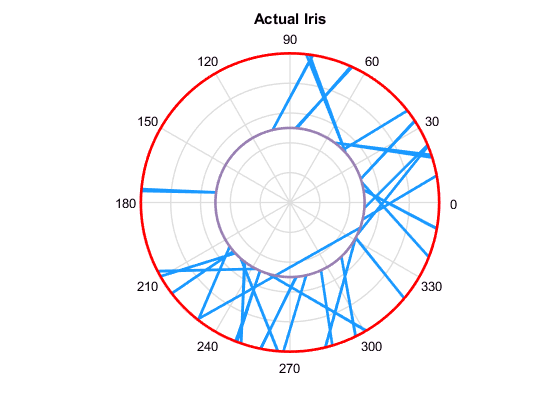

actual = diffPDs.Variables;
muscle = modelDiffPDs{2}.Variables;
handle = modelDiffPDs{1}.Variables;

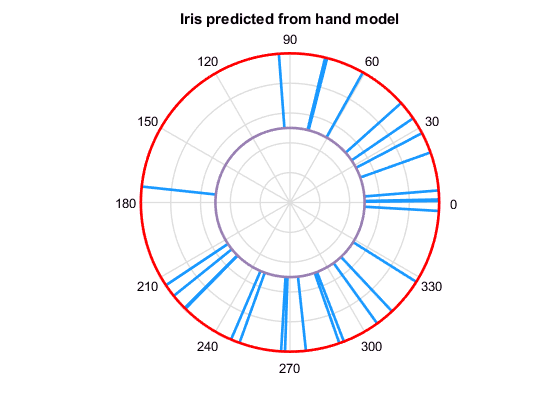


muscleLinModel = fitlm(actual(:),muscle(:))
handleLinModel = fitlm(actual(:),handle(:))


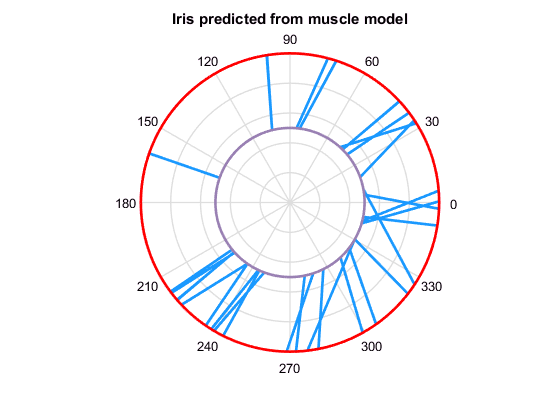

figure
plot(actual(:),muscle(:),'bo','linewidth',2)
hold on
plot(actual(:),handle(:),'rx','linewidth',2)

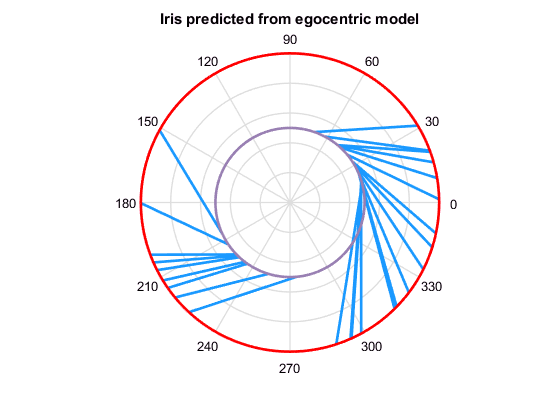

plot([0 0],[-pi pi],'k-')
plot([-pi pi],[0 0],'k-')
plot([-pi pi],[-pi pi],'k--','linewidth',2)
plot(actual(:),muscle(:),'bo','linewidth',2)

plot(actual(:),handle(:),'rx','linewidth',2)
plot([-pi;pi],muscleLinModel.predict([-pi;pi]),'b-','linewidth',1)
plot([-pi;pi],handleLinModel.predict([-pi;pi]),'r-','linewidth',1)
% xlim([-pi pi])

muscleLinModel = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)    -0.064196    0.048604    -1.3208       0.19339
    x1               0.30867    0.068413     4.5119    4.7425e-05


Number of observations: 46, Error degrees of freedom: 44
Root Mean Squared Error: 0.326
R-squared: 0.316,  Adjusted R-Squared 0.301
F-statistic vs. constant model: 20.4, p-value = 4.74e-05

% ylim([-pi pi])

handleLinModel = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue 
                   ___________    __________    ________    ________

    (Intercept)     1.8726e-15    1.0466e-15      1.7892    0.080464
    x1             -1.4271e-15    1.4731e-15    -0.96876     0.33796


Number of observations: 46, Error degrees of freedom: 44
Root Mean Squared Error: 7.02e-15
R-squared: 0.0209,  Adjusted R-Squared -0.00137
F-statistic vs. constant model: 0.939, p-value = 0.338

axis equal

egoLinModel = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________

    (Intercept)    -0.88192    0.056238     -15.682    1.2516e-19
    x1             0.003695    0.079158    0.046678       0.96298


Number of observations: 46, Error degrees of freedom: 44
Root Mean Squared Error: 0.377
R-squared: 4.95e-05,  Adjusted R-Squared -0.0227
F-statistic vs. constant model: 0.00218, p-value = 0.963

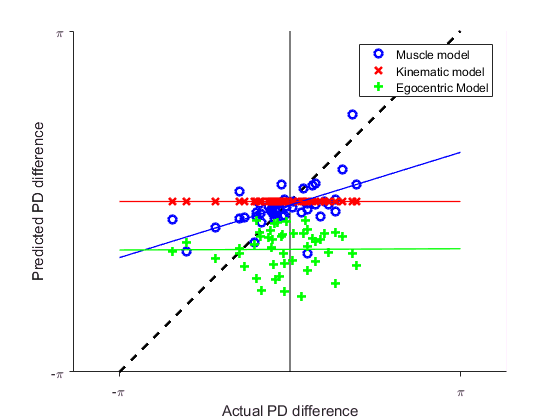

muscleLinModel = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE       tStat       pValue  
                   _________    ________    ______    __________

    (Intercept)    -0.070202    0.015705     -4.47    9.8735e-06
    x1               0.25955    0.020143    12.885    1.2412e-32


Number of observations: 460, Error degrees of freedom: 458
Root Mean Squared Error: 0.334
R-squared: 0.266,  Adjusted R-Squared 0.264
F-statistic vs. constant model: 166, p-value = 1.24e-32

handleLinModel = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)     1.9305e-15     4.714e-16     4.0952    4.9865e-05
    x1             -1.4424e-15    6.0461e-16    -2.3857      0.017451


Number of observations: 460, Error degrees of freedom: 458
Root Mean Squared Error: 1e-14
R-squared: 0.0123,  Adjusted R-Squared 0.0101
F-statistic vs. constant model: 5.69, p-value = 0.0175

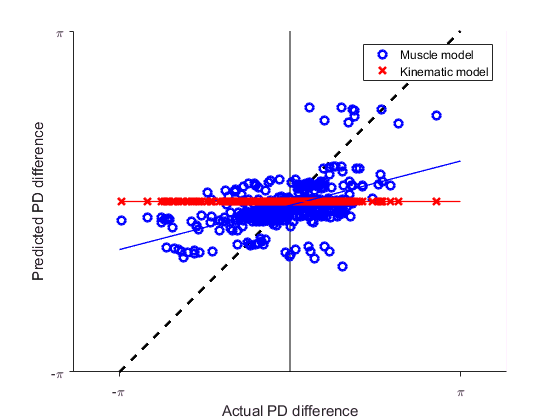

set(gca,'box','off','tickdir','out','xtick',[-pi pi],'ytick',[-pi pi],'xticklabel',{'-\pi','\pi'},'yticklabel',{'-\pi','\pi'})
% axis off
xlabel('Actual PD difference')
ylabel('Predicted PD difference')
legend('Muscle model','Kinematic model')

clear muscleLinModel
clear handleLinModel